Lab 5

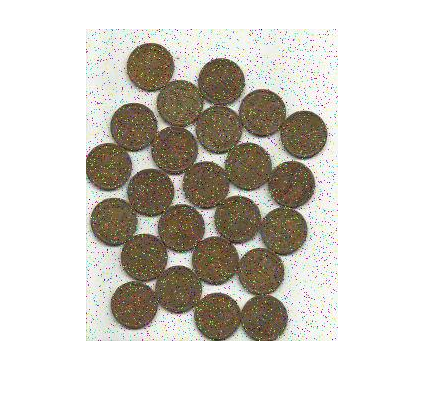

Image = LoadImage('corrupted_coins.jpg');

HistoGram

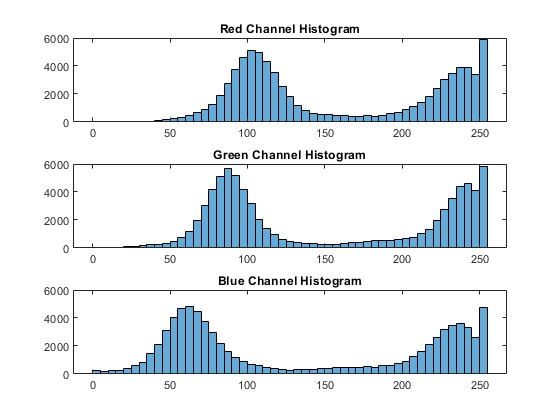

figure
title("Image Histograms");
subplot(3,1,1);
histogram(Image(:,:,1))
title("Red Channel Histogram");
subplot(3,1,2);
histogram(Image(:,:,2));
title("Green Channel Histogram");
subplot(3,1,3);
histogram(Image(:,:,3));
title("Blue Channel Histogram");

Mean Filter

filter = 1/3 * ones(3);
disp(filter)

    0.3333    0.3333    0.3333
    0.3333    0.3333    0.3333
    0.3333    0.3333    0.3333



imshow(convolve(Image, filter, 1));

Error using  * 
MTIMES (*) is not fully supported for integer classes. At least one argument must be scalar.

Error in convolve (line 28)
                layerOutput(x - xOffset, y-yOffset) = (View * filter);      